%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( Bsquaredreal, twoVoverRsquared );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );


hold on

%Creating errors on data
ypos=((4.*(100)./(r.^4))+(16.*(0.001.^2).*(voltage.^2)./(r.^6))).^(1./2)

ypos = 	1.0e+04 *

    7.8102    6.4031    7.0711    7.4330    2.5185    2.6708    3.1427    4.0680    1.6008    2.1506    1.4266    1.8125    1.0245    0.8503    0.9169    1.3505


yneg=ypos;
xpos=(1.0e-16.*(6.9236.^4).*.4.*(current.^2).*0.1.^2).^(1/2)

xpos = 	1.0e+-7 *

    0.7883    0.6064    0.7276    0.7579    0.3032    0.4548    0.6064    0.7579    0.4548    0.6064    0.3335    0.5154    0.3941    0.1516    0.3032    0.5154


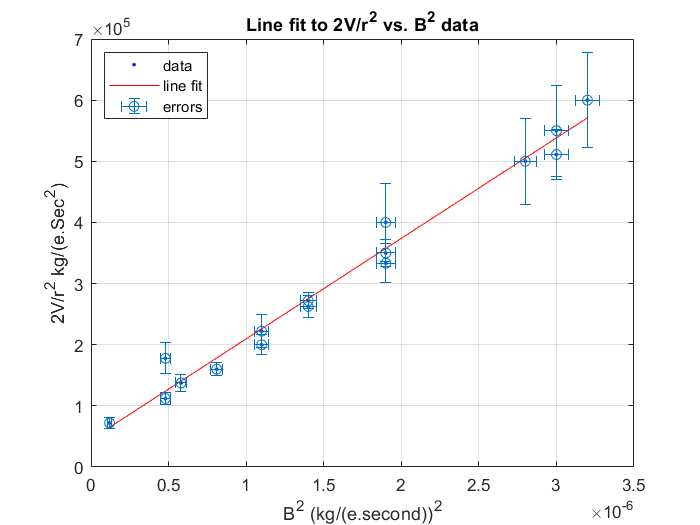

xneg=xpos;
errorbar(Bsquaredreal,twoVoverRsquared,yneg,ypos,xneg,xpos,'o');


% Label axes

grid on

legend({'data','line fit','errors'},'Location','northwest')
xlabel('B^2 (kg/(coulomb.second))^2')
ylabel('2V/r^2 kg/(coulomb.Sec^2)')
title('Line fit to 2V/r^2 vs. B^2 data')

%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds) meaning 2 sigma. In the report it is corrected to 1 sigma:
 %      p1 =   1.644e+11  (1.508e+11, 1.779e+11)
  %     p2 =   4.523e+04  (2.013e+04, 7.032e+04)

%Goodness of fit:
 % SSE: 8.472e+09
 % R-square: 0.9797
 % Adjusted R-square: 0.9782
  %RMSE: 2.46e+04